# Ejemplos de distribuciones

En este livescript se presenta ejemplos de distribuciones, sus estadísticas mas comunes y como interpretarlas

## Distribución uniforme

Se presenta cuando todos los posibles escenarios tienen igual oportunidad de ocurrir

Simulamos la selección de 6 números al azar durante 12,000 lanzamientos

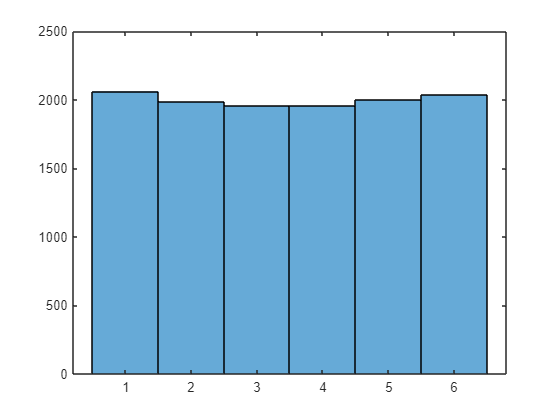

N = 12000;
rollVals = randi(6,[N,1]);
histogram(rollVals)

numObs = N/6

numObs = 2000

### Estadística descriptiva:

promedio y desviación estandar

uAvg = mean(rollVals)

uAvg = 3.4963

uSd = std(rollVals)

uSd = 1.7218

## Distribución normal

En el caso de una distribución normal, la probabilidad de cada evento está en relación con su distancia de la media o promedio ($\mu$). Los datos están distribuidos simétricamente, aproximadamente 2/3 de los datos se encuentran bajo la primer desviación estndard ($\sigma$) 

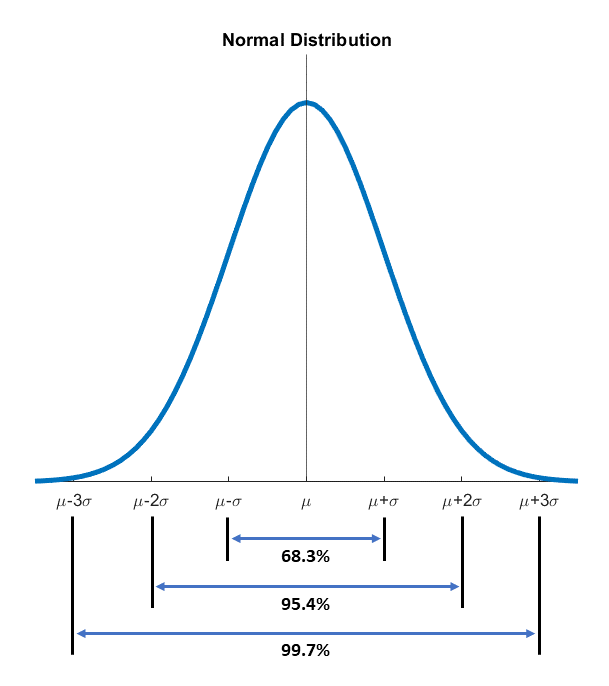

## Distribuciones con sesgo 

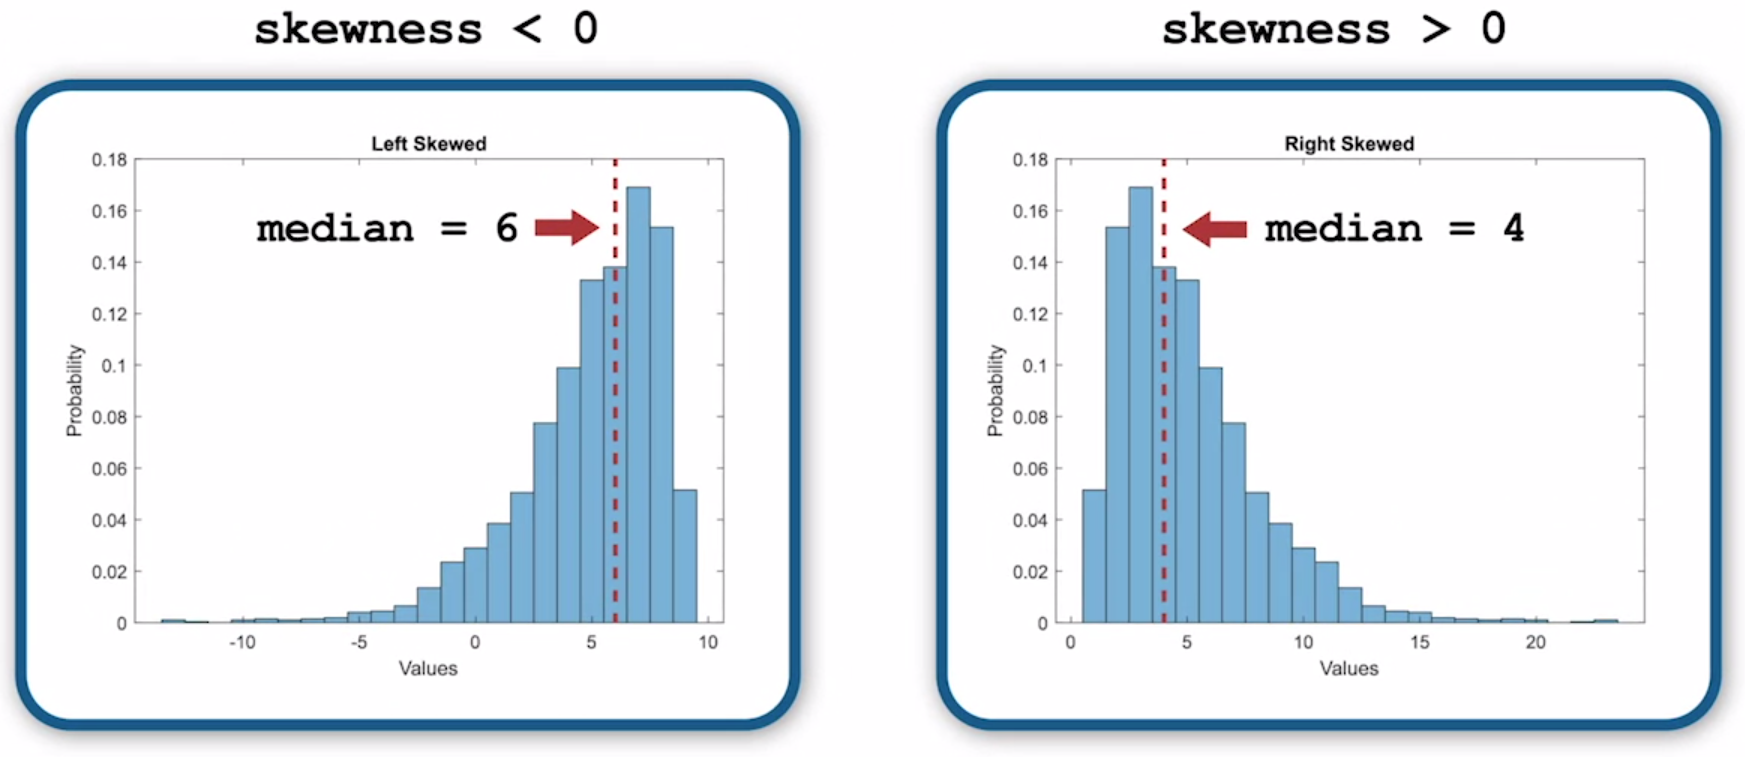

El valor del tercer momento central, sesgo, puede indicarnos cómo están distribuidos los datos alrededor de un valor central, donde es de mayor utilidad el uso de la mediana para establecer un valor medio que asegure un balance entre ambas mitades. La desviación estandar no es de utilidad para describir este tipo de distribuciones debido a que la media no garantiza la división de datos en cantidades similares

## Interquartile Range (IQR)

el rango intercuartílico nos proporciona una medida de dispersión que utiliza la mediana como valor central

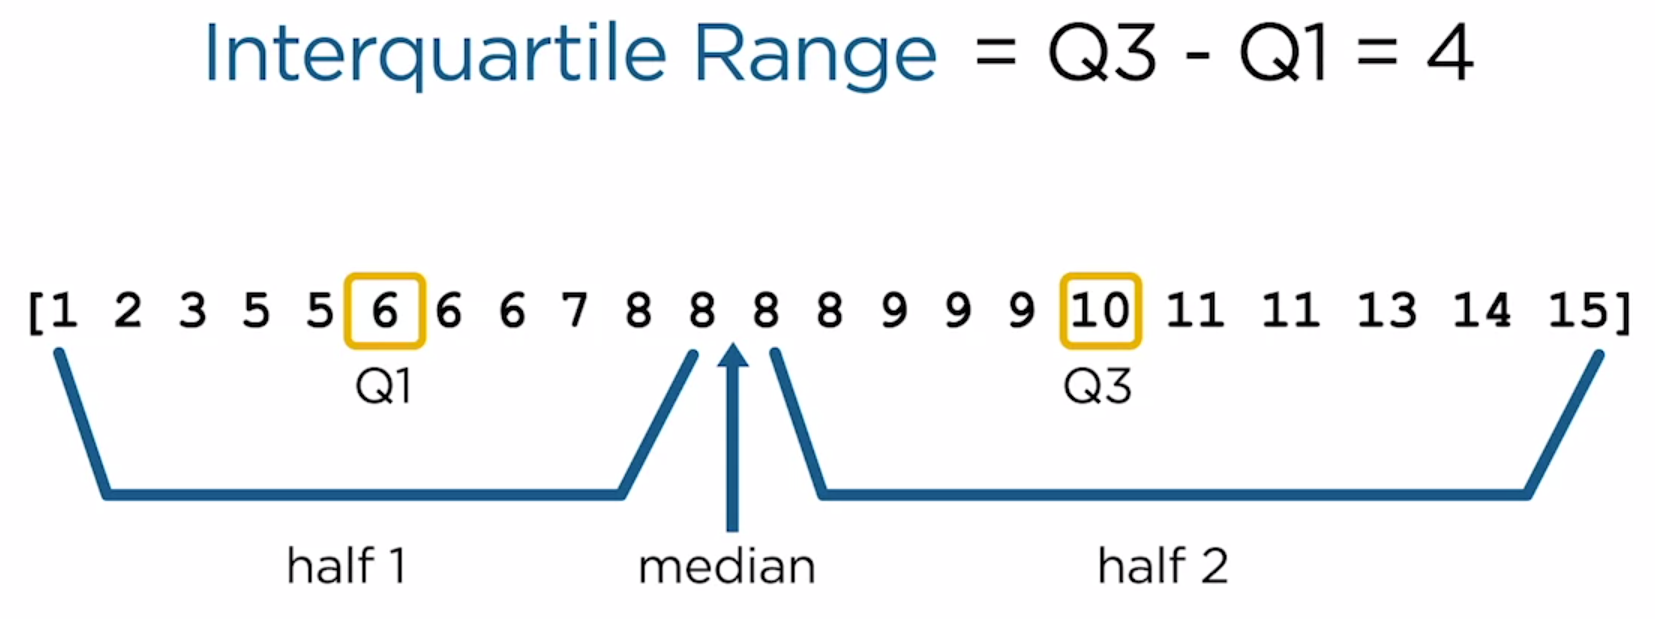

Para visualizar una distribución sesgada e incluso comparar distribuciones, se utiliza la gráfica de caja (Box plot)

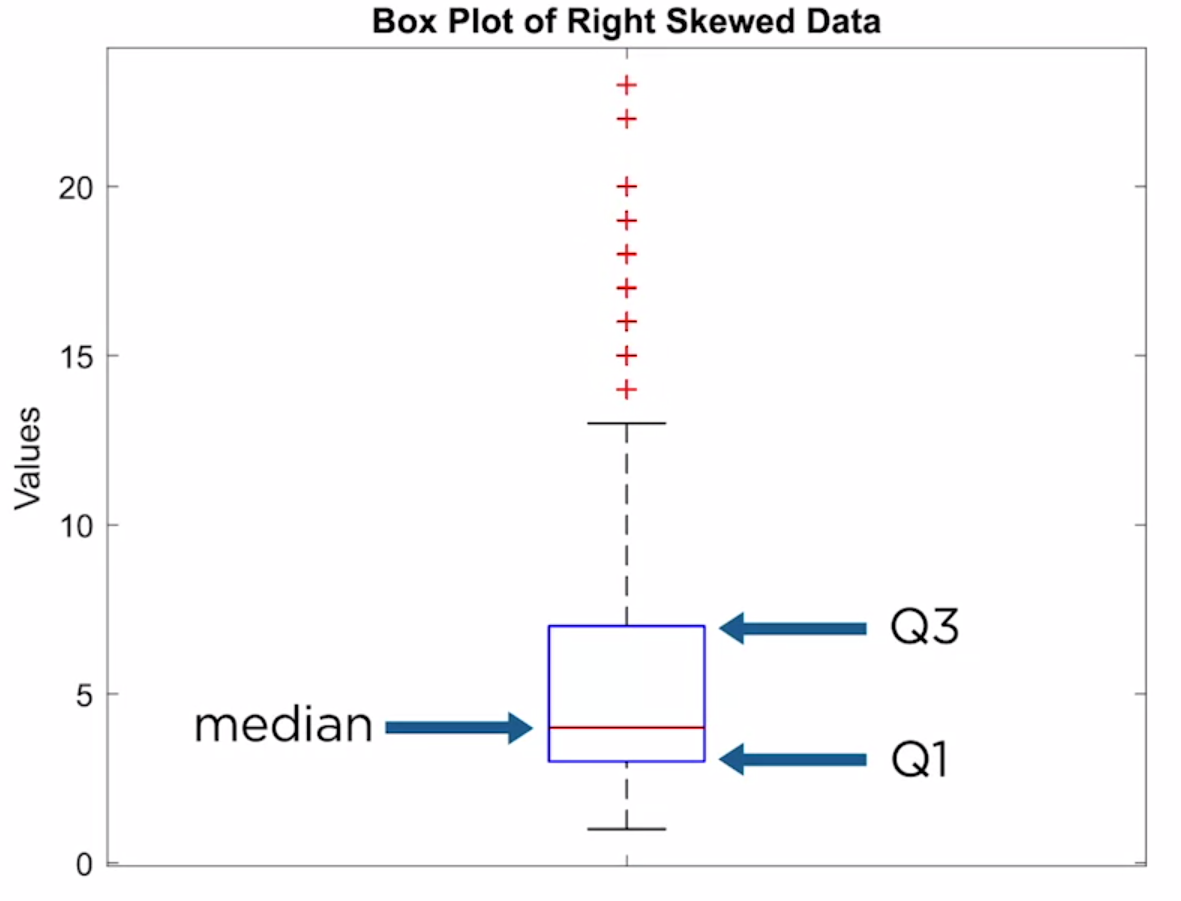

Con las gráficas de caja es posible comparar varias distribuciones en una sola figura

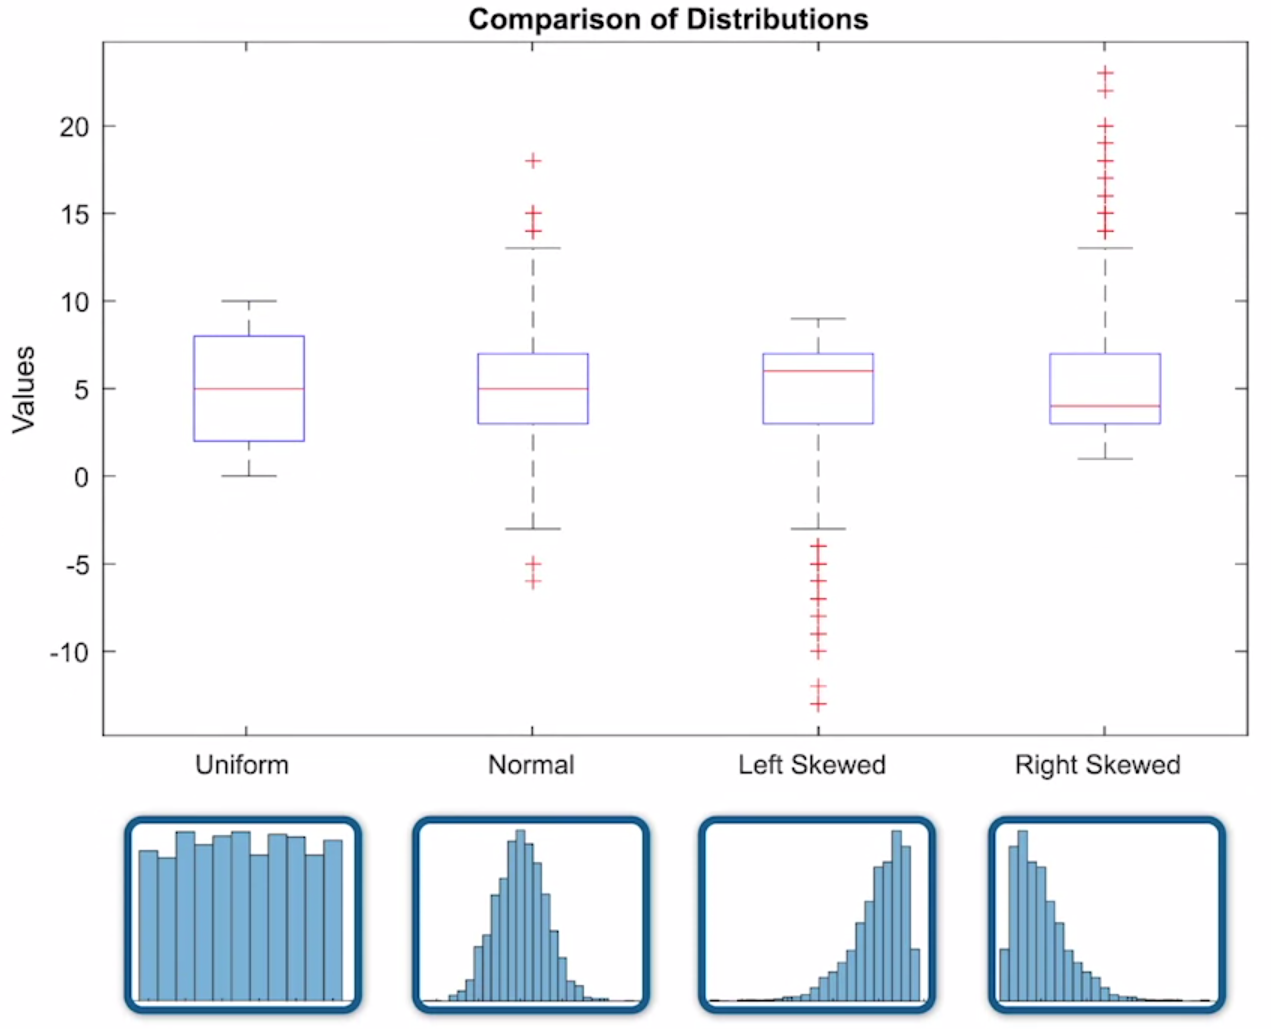

El promedio y desviación estandar para las 4 distribuciones son iguales en este ejemplo

Generemos una distribución que esté sesgada hacia la izquierda y comparemos los descriptores estadísticos de tendencia central (media y mediana) y de dispersión (desviación estandar, rango intercuartil) así como los comandos para obtener percentiles o especificar el rango a algun valor específico

Primero vamos a generar una distribución sesgada

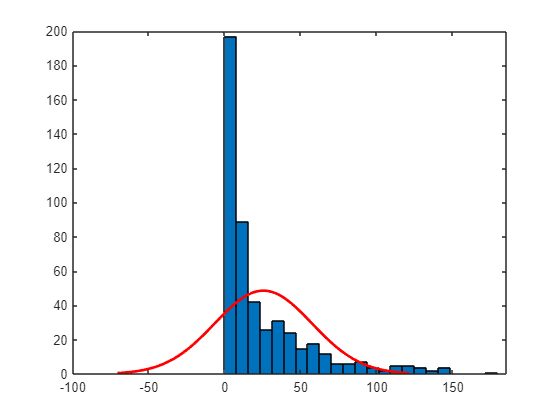

x = gamrnd(0.5,50,1,500);
histfit(x)

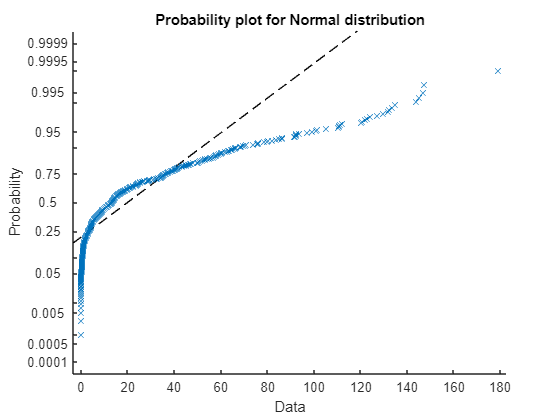

probplot('normal',x)

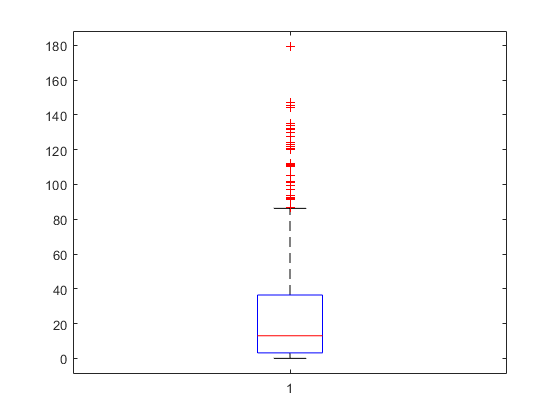

boxplot(x)

Obtengamos las medidas de tendencia central y de dispersión

valor_promedio = mean(x)

valor_promedio = 25.2744

valor_mediana = median(x)

valor_mediana = 13.0506

desv_std = std(x)

desv_std = 32.0069

rango_interquartil = iqr(x)

rango_interquartil = 33.2997

quartiles = quantile(x,[0.25, 0.5, 0.75])

quartiles =     3.1612   13.0506   36.4609


% comprombamos que rango intercuartil es igual a Q3 - Q1
quartiles(3) - quartiles(1)

ans = 33.2997

Vamos a graficar el histograma comparando ambos métodos

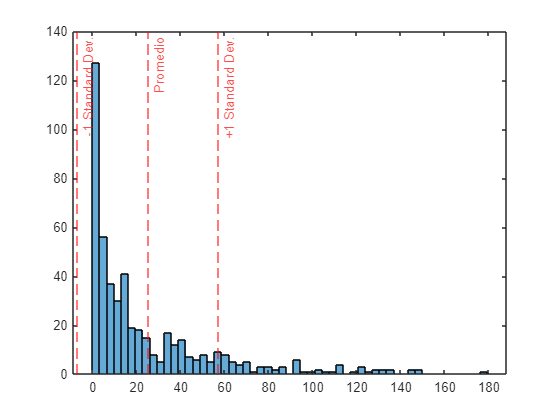

bins = 55;
histogram(x, bins)
xline([valor_promedio-desv_std valor_promedio valor_promedio+desv_std],'--r',{'-1 Standard Dev.','Promedio','+1 Standard Dev.'})

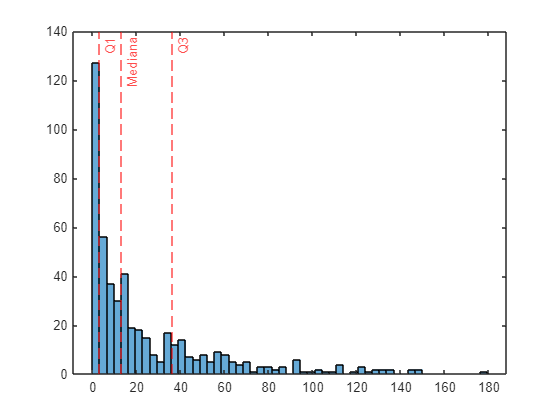

histogram(x, bins)
xline([quartiles(1) valor_mediana quartiles(3)],'--r',{'Q1','Mediana','Q3'})

percentil_90 = prctile(x,90)

percentil_90 = 66.5930

percentil_10 = prctile(x,10)

percentil_10 = 0.6745

% Percentil 50 es igual que la mediana
percentil_50 = prctile(x,50)

percentil_50 = 13.0506

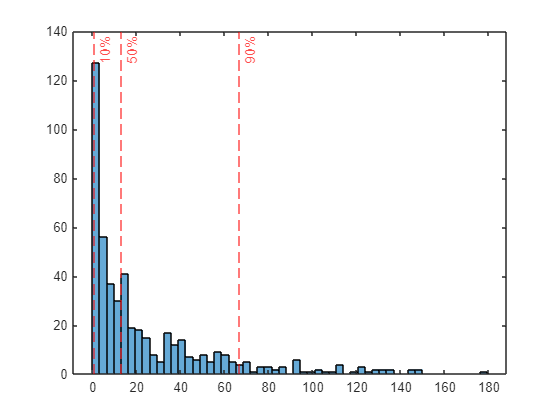

histogram(x, bins)
xline([percentil_10 percentil_50 percentil_90],'--r',{'10%','50%','90%'})